###  Plotting mean and standard error of G1 and G2 of all dataset

% CBD: Rat10, Rat212
% VEH: Rat210, Rat213
%.......................

# **CBD ( Rat10, Rat212 )**

% Calculate mean for each row and for even and odd indices separately
Rat10_CBD_CSWR=load("E:\Genzellab\Projects\Current Source Density\Codes\Rat10_2Gen\rat10.GC_CSWR_End\Rat10(CBD)-cswr_2Gen.mat").results

Rat10_CBD_CSWR = 1×7 struct array with fields:
    spatialWeightsMatrix
    timeCoursesMatrix


Rat10_CBD_Ripple=load("E:\Genzellab\Projects\Current Source Density\Codes\Rat10_2Gen\rat10.GC_Ripple_End\Rat10(CBD)-Ripp_2Gen.mat").results

Rat10_CBD_Ripple = 1×694 struct array with fields:
    spatialWeightsMatrix
    timeCoursesMatrix


Rat10_CBD_SW=load("E:\Genzellab\Projects\Current Source Density\Codes\Rat10_2Gen\rat10.GC_SW_End\Rat10(CBD)-SW_2Gen.mat").results

Rat10_CBD_SW = 1×61 struct array with fields:
    spatialWeightsMatrix
    timeCoursesMatrix


Rat10_CBD_SWR=load("E:\Genzellab\Projects\Current Source Density\Codes\Rat10_2Gen\rat10.GC_SWR_End\Rat10(CBD)-SWR_2Gen.mat").results

Rat10_CBD_SWR = 1×97 struct array with fields:
    spatialWeightsMatrix
    timeCoursesMatrix



Rat212_CBD_CSWR=load("E:\Genzellab\Projects\Current Source Density\Codes\Rat212_2Gen\rat212.GC_CSWR_End\Rat212(CBD)-cswr_2Gen.mat").results

Rat212_CBD_CSWR = 1×82 struct array with fields:
    spatialWeightsMatrix
    timeCoursesMatrix


Rat212_CBD_Ripple=load("E:\Genzellab\Projects\Current Source Density\Codes\Rat212_2Gen\rat212.GC_Ripple_End\Rat212(CBD)-Ripp_2Gen.mat").results

Rat212_CBD_Ripple = 1×82 struct array with fields:
    spatialWeightsMatrix
    timeCoursesMatrix


Rat212_CBD_SW=load("E:\Genzellab\Projects\Current Source Density\Codes\Rat212_2Gen\rat212.GC_SW_End\Rat212(CBD)-SW_2Gen.mat").results

Rat212_CBD_SW = 1×224 struct array with fields:
    spatialWeightsMatrix
    timeCoursesMatrix


Rat212_CBD_SWR=load("E:\Genzellab\Projects\Current Source Density\Codes\Rat212_2Gen\rat212.GC_SWR_End\Rat212(CBD)-SWR_2Gen.mat").results

Rat212_CBD_SWR = 1×202 struct array with fields:
    spatialWeightsMatrix
    timeCoursesMatrix



Channels = 32;
Generators = 2;
%................................
%Rat10_CSWR
Events = numel(Rat10_CBD_CSWR); % assuming yourStruct is the name of your struct
Generators_Rat10_CSWR = zeros(Events,Channels, Generators);
% Step 2-4: Extract and store the specific field in the 3D matrix      
for i = 1:Events
    specificField = Rat10_CBD_CSWR(i).spatialWeightsMatrix; 
    reshapedField = reshape(specificField, Channels, Generators);
    Generators_Rat10_CSWR(i, :, :) = reshapedField;
end 
.................................
%Rat10_Ripple
Events = numel(Rat10_CBD_Ripple); 
Generators_Rat10_Ripple = zeros(Events,Channels, Generators);
% Step 2-4: Extract and store the specific field in the 3D matrix       
for i = 1:Events
    specificField = Rat10_CBD_Ripple(i).spatialWeightsMatrix; 
    reshapedField = reshape(specificField, Channels, Generators);
    Generators_Rat10_Ripple(i, :, :) = reshapedField;
end 
%................................
%Rat10_SW
Events = numel(Rat10_CBD_SW); 
Generators_Rat10_SW = zeros(Events,Channels, Generators);
% Step 2-4: Extract and store the specific field in the 3D matrix       
for i = 1:Events
    specificField = Rat10_CBD_SW(i).spatialWeightsMatrix; 
    reshapedField = reshape(specificField, Channels, Generators);
    Generators_Rat10_SW(i, :, :) = reshapedField;
end 
%...............................
%Rat10_SWR
Events = numel(Rat10_CBD_SWR); 
Generators_Rat10_SWR = zeros(Events,Channels, Generators);
% Step 2-4: Extract and store the specific field in the 3D matrix       
for i = 1:Events
    specificField = Rat10_CBD_SWR(i).spatialWeightsMatrix; 
    reshapedField = reshape(specificField, Channels, Generators);
    Generators_Rat10_SWR(i, :, :) = reshapedField;
end
%...............................
%Rat212_CSWR
Events = numel(Rat212_CBD_CSWR); % assuming yourStruct is the name of your struct
Generators_Rat212_CSWR = zeros(Events,Channels, Generators);
% Step 2-4: Extract and store the specific field in the 3D matrix      
for i = 1:Events
    specificField = Rat212_CBD_CSWR(i).spatialWeightsMatrix; 
    reshapedField = reshape(specificField,Channels, Generators);
    Generators_Rat212_CSWR(i, :, :) = reshapedField;
end 
.................................
%Rat212_Ripple
Events = numel(Rat212_CBD_Ripple);
Generators_Rat212_Ripple = zeros(Events,Channels, Generators);
% Step 2-4: Extract and store the specific field in the 3D matrix       
for i = 1:Events
    specificField = Rat212_CBD_Ripple(i).spatialWeightsMatrix; 
    reshapedField = reshape(specificField, Channels, Generators);
    Generators_Rat212_Ripple(i, :, :) = reshapedField;
end 
%................................
%Rat212_SW
Events = numel(Rat212_CBD_SW); 
Generators_Rat212_SW = zeros(Events,Channels, Generators);
% Step 2-4: Extract and store the specific field in the 3D matrix       
for i = 1:Events
    specificField = Rat212_CBD_SW(i).spatialWeightsMatrix; 
    reshapedField = reshape(specificField, Channels, Generators);
    Generators_Rat212_SW(i, :, :) = reshapedField;
end 
%...............................
%Rat212_SWR
Events = numel(Rat212_CBD_SWR); 
Generators_Rat212_SWR = zeros(Events,Channels, Generators);
% Step 2-4: Extract and store the specific field in the 3D matrix       
for i = 1:Events
    specificField = Rat212_CBD_SWR(i).spatialWeightsMatrix; 
    reshapedField = reshape(specificField, Channels, Generators);
    Generators_Rat212_SWR(i, :, :) = reshapedField;
end

# **VEH ( Rat210, Rat213 )**

% Calculate mean for each row and for even and odd indices separately
Rat210_VEH_CSWR=load("E:\Genzellab\Projects\Current Source Density\Codes\Rat210_2Gen\rat210.GC_CSWR_End\Rat210(VEH)-cswr_2Gen.mat").results

Rat210_VEH_CSWR = 1×59 struct array with fields:
    spatialWeightsMatrix
    timeCoursesMatrix


Rat210_VEH_Ripple=load("E:\Genzellab\Projects\Current Source Density\Codes\Rat210_2Gen\rat210.GC_Ripple_End\Rat210(VEH)-Ripp_2Gen.mat").results

Rat210_VEH_Ripple = 1×330 struct array with fields:
    spatialWeightsMatrix
    timeCoursesMatrix


Rat210_VEH_SW=load("E:\Genzellab\Projects\Current Source Density\Codes\Rat210_2Gen\rat210.GC_SW_End\Rat210(VEH)-SW_2Gen.mat").results

Rat210_VEH_SW = 1×187 struct array with fields:
    spatialWeightsMatrix
    timeCoursesMatrix


Rat210_VEH_SWR=load("E:\Genzellab\Projects\Current Source Density\Codes\Rat210_2Gen\rat210.GC_SWR_End\Rat210(VEH)-SWR_2Gen.mat").results

Rat210_VEH_SWR = 1×283 struct array with fields:
    spatialWeightsMatrix
    timeCoursesMatrix



Rat213_VEH_CSWR=load("E:\Genzellab\Projects\Current Source Density\Codes\Rat213_2Gen\rat213.GC_CSWR_End\Rat213(VEH)-cswr_2Gen.mat").results

Rat213_VEH_CSWR = 1×82 struct array with fields:
    spatialWeightsMatrix
    timeCoursesMatrix


Rat213_VEH_Ripple=load("E:\Genzellab\Projects\Current Source Density\Codes\Rat213_2Gen\rat213.GC_Ripple_End\Rat213(VEH)-Ripp_2Gen.mat").results

Rat213_VEH_Ripple = 1×65 struct array with fields:
    spatialWeightsMatrix
    timeCoursesMatrix


Rat213_VEH_SW=load("E:\Genzellab\Projects\Current Source Density\Codes\Rat213_2Gen\rat213.GC_SW_End\Rat213(VEH)-SW_2Gen.mat").results

Rat213_VEH_SW = 1×391 struct array with fields:
    spatialWeightsMatrix
    timeCoursesMatrix


Rat213_VEH_SWR=load("E:\Genzellab\Projects\Current Source Density\Codes\Rat213_2Gen\rat213.GC_SWR_End\Rat213(VEH)-SWR_2Gen.mat").results

Rat213_VEH_SWR = 1×117 struct array with fields:
    spatialWeightsMatrix
    timeCoursesMatrix


%.....................................
%Rat210_CSWR
Events = numel(Rat210_VEH_CSWR); % assuming yourStruct is the name of your struct
Generators_Rat210_CSWR = zeros(Events,Channels, Generators);
% Step 2-4: Extract and store the specific field in the 3D matrix      
for i = 1:Events
    specificField = Rat210_VEH_CSWR(i).spatialWeightsMatrix; 
    reshapedField = reshape(specificField, Channels, Generators);
    Generators_Rat210_CSWR(i, :, :) = reshapedField;
end 
.................................
%Rat210_Ripple
Events = numel(Rat210_VEH_Ripple); 
Generators_Rat210_Ripple = zeros(Events,Channels, Generators);
% Step 2-4: Extract and store the specific field in the 3D matrix       
for i = 1:Events
    specificField = Rat210_VEH_Ripple(i).spatialWeightsMatrix; 
    reshapedField = reshape(specificField, Channels, Generators);
    Generators_Rat210_Ripple(i, :, :) = reshapedField;
end 
%................................
%Rat210_SW
Events = numel(Rat210_VEH_SW); 
Generators_Rat210_SW = zeros(Events,Channels, Generators);
% Step 2-4: Extract and store the specific field in the 3D matrix       
for i = 1:Events
    specificField = Rat210_VEH_SW(i).spatialWeightsMatrix; 
    reshapedField = reshape(specificField, Channels, Generators);
    Generators_Rat210_SW(i, :, :) = reshapedField;
end 
%...............................
%Rat210_SWR
Events = numel(Rat210_VEH_SWR); 
Generators_Rat210_SWR = zeros(Events,Channels, Generators);
% Step 2-4: Extract and store the specific field in the 3D matrix       
for i = 1:Events
    specificField = Rat210_VEH_SWR(i).spatialWeightsMatrix; 
    reshapedField = reshape(specificField, Channels, Generators);
    Generators_Rat210_SWR(i, :, :) = reshapedField;
end
%...............................
%Rat213_CSWR
Events = numel(Rat213_VEH_CSWR); % assuming yourStruct is the name of your struct
Generators_Rat213_CSWR = zeros(Events,Channels, Generators);
% Step 2-4: Extract and store the specific field in the 3D matrix      
for i = 1:Events
    specificField = Rat213_VEH_CSWR(i).spatialWeightsMatrix; 
    reshapedField = reshape(specificField,Channels, Generators);
    Generators_Rat213_CSWR(i, :, :) = reshapedField;
end 
.................................
%Rat213_Ripple
Events = numel(Rat213_VEH_Ripple);
Generators_Rat213_Ripple = zeros(Events,Channels, Generators);
% Step 2-4: Extract and store the specific field in the 3D matrix       
for i = 1:Events
    specificField = Rat213_VEH_Ripple(i).spatialWeightsMatrix; 
    reshapedField = reshape(specificField, Channels, Generators);
    Generators_Rat213_Ripple(i, :, :) = reshapedField;
end 
%................................
%Rat213_SW
Events = numel(Rat213_VEH_SW); 
Generators_Rat213_SW = zeros(Events,Channels, Generators);
% Step 2-4: Extract and store the specific field in the 3D matrix       
for i = 1:Events
    specificField = Rat213_VEH_SW(i).spatialWeightsMatrix; 
    reshapedField = reshape(specificField, Channels, Generators);
    Generators_Rat213_SW(i, :, :) = reshapedField;
end 
%...............................
%Rat213_SWR
Events = numel(Rat213_VEH_SWR); 
Generators_Rat213_SWR = zeros(Events,Channels, Generators);
% Step 2-4: Extract and store the specific field in the 3D matrix       
for i = 1:Events
    specificField = Rat213_VEH_SWR(i).spatialWeightsMatrix; 
    reshapedField = reshape(specificField, Channels, Generators);
    Generators_Rat213_SWR(i, :, :) = reshapedField;
end

# Plots

% Mean of CBD
Average_CBD_CSWR= squeeze(mean(Generators_Rat10_CSWR,1)+mean(Generators_Rat212_CSWR,1))/2

Average_CBD_CSWR =     0.3476    0.2855
    0.3412    0.3208
    0.3457    0.3181
    0.3392    0.3128
    0.3295    0.3250
    0.3241    0.3258
    0.3033    0.0696
    0.3050    0.2709
    0.3115    0.0715
    0.3419   -0.2532


Average_CBD_Ripple= squeeze(mean(Generators_Rat10_Ripple,1)+mean(Generators_Rat212_Ripple,1))/2

Average_CBD_Ripple =     0.2040    0.0559
    0.2124   -0.0827
    0.2170   -0.1559
    0.2239   -0.1667
    0.2275   -0.1878
    0.2253   -0.1562
    0.2123    0.0687
    0.2126   -0.0590
    0.2070   -0.0777
    0.2133   -0.3356


Average_CBD_SW= squeeze(mean(Generators_Rat10_SW,1)+mean(Generators_Rat212_SW,1))/2

Average_CBD_SW =     0.2215   -0.0428
    0.2261   -0.0671
    0.2315   -0.0294
    0.2434   -0.0235
    0.2502    0.0104
    0.2477    0.0972
    0.2217    0.2158
    0.2320    0.2844
    0.2331    0.5857
    0.2587    0.7270


Average_CBD_SWR= squeeze(mean(Generators_Rat10_SWR,1)+mean(Generators_Rat212_SWR,1))/2

Average_CBD_SWR =     0.2088    1.6499
    0.2104    1.6986
    0.2136    1.7318
    0.2202    1.8007
    0.2231    1.8285
    0.2205    1.8344
    0.2180    1.6408
    0.2082    1.7608
    0.1940    1.8007
    0.1914    2.2056



% Mean of VEH
Average_VEH_CSWR=squeeze(mean(Generators_Rat210_CSWR,1)+mean(Generators_Rat213_CSWR,1))/2

Average_VEH_CSWR =     0.0683    0.3500
    0.0656    0.3719
    0.0618    0.4224
    0.0602    0.4646
    0.0564    0.5729
    0.0556    0.6344
    0.0663    0.6581
    0.1052    0.6947
    0.1884    1.1667
    0.2658    1.5304


Average_VEH_Ripple=squeeze(mean(Generators_Rat210_Ripple,1)+mean(Generators_Rat213_Ripple,1))/2

Average_VEH_Ripple =     0.0970    0.2848
    0.0926    0.2505
    0.0894    0.2221
    0.0863    0.1846
    0.0840    0.1718
    0.0837    0.1710
    0.0912    0.2595
    0.1148    0.4952
    0.1728    0.3350
    0.2187   -0.0041


Average_VEH_SW=squeeze(mean(Generators_Rat210_SW,1)+mean(Generators_Rat213_SW,1))/2

Average_VEH_SW =     0.2064    0.3414
    0.2035    0.3220
    0.1992    0.3127
    0.1983    0.2960
    0.1980    0.2586
    0.2027    0.2004
    0.2172    0.0966
    0.2526   -0.0965
    0.3279   -0.4170
    0.3928   -0.6967


Average_VEH_SWR=squeeze(mean(Generators_Rat210_SWR,1)+mean(Generators_Rat213_SWR,1))/2

Average_VEH_SWR =     0.1082    0.4980
    0.1066    0.5432
    0.1040    0.5715
    0.1041    0.5916
    0.1038    0.6221
    0.1054    0.5974
    0.1176    0.4549
    0.1610    0.0845
    0.2665   -0.5970
    0.3596   -1.2440


%.....................
% Standard Error of the mean - CBD
Sem_CBD_CSWR = squeeze(std(cat(1,Generators_Rat10_CSWR,Generators_Rat212_CSWR), 1) / sqrt(size(cat(1,Generators_Rat10_CSWR,Generators_Rat212_CSWR), 1)));
Sem_CBD_Ripple = squeeze(std(cat(1,Generators_Rat10_Ripple,Generators_Rat212_Ripple),1) / sqrt(size(cat(1,Generators_Rat10_Ripple,Generators_Rat212_Ripple), 1)));
Sem_CBD_SW = squeeze(std(cat(1,Generators_Rat10_SW,Generators_Rat212_SW),1) / sqrt(size(cat(1,Generators_Rat10_SW,Generators_Rat212_SW), 1)));
Sem_CBD_SWR = squeeze(std(cat(1,Generators_Rat10_SWR,Generators_Rat212_SWR),1) / sqrt(size(cat(1,Generators_Rat10_SWR,Generators_Rat212_SWR), 1)));
% Standard Error of the mean - VEH
Sem_VEH_CSWR = squeeze(std(cat(1,Generators_Rat210_CSWR,Generators_Rat213_CSWR), 1) / sqrt(size(cat(1,Generators_Rat210_CSWR,Generators_Rat213_CSWR), 1)));
Sem_VEH_Ripple = squeeze(std(cat(1,Generators_Rat210_Ripple,Generators_Rat213_Ripple),1) / sqrt(size(cat(1,Generators_Rat210_Ripple,Generators_Rat213_Ripple), 1)));
Sem_VEH_SW = squeeze(std(cat(1,Generators_Rat210_SW,Generators_Rat213_SW),1) / sqrt(size(cat(1,Generators_Rat210_SW,Generators_Rat213_SW), 1)));
Sem_VEH_SWR = squeeze(std(cat(1,Generators_Rat210_SWR,Generators_Rat213_SWR),1) / sqrt(size(cat(1,Generators_Rat210_SWR,Generators_Rat213_SWR), 1)));
%..........................................
%G1
figure;
timevect=1:32

timevect =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32


[hl_g1, hp_g1] = boundedline( ...
     Average_CBD_CSWR(:,1),timevect,  Sem_CBD_CSWR(:,1)' ,'k', 'alpha', ...
     Average_CBD_Ripple(:,1),timevect,Sem_CBD_Ripple(:,1)','c','alpha', ...
     Average_CBD_SW(:,1),timevect,    Sem_CBD_SW(:,1)','r','alpha',  ...
     Average_CBD_SWR(:,1),timevect,   Sem_CBD_SWR(:,1)','b','alpha',  ...
     Average_VEH_CSWR(:,1),timevect,  Sem_VEH_CSWR(:,1)' ,'g','alpha', ...
     Average_VEH_Ripple(:,1),timevect,Sem_VEH_Ripple(:,1)','m','alpha',...
     Average_VEH_SW(:,1),timevect,    Sem_VEH_SW(:,1)','y','alpha',  ...
     Average_VEH_SWR(:,1),timevect,   Sem_VEH_SWR(:,1)','b','alpha', 'orientation', 'horiz')

hl_g1 =   8×1 Line array:

  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line


hp_g1 =   8×1 Patch array:

  Patch
  Patch
  Patch
  Patch
  Patch
  Patch
  Patch
  Patch


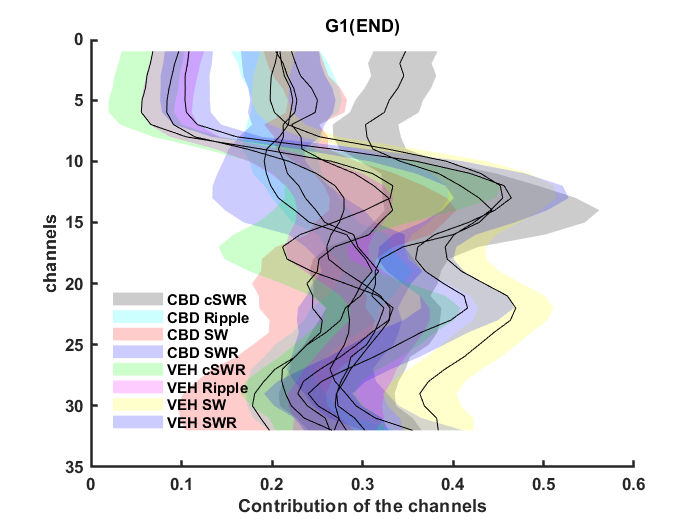


% Set line properties (black lines)
set(hl_g1, 'Color', 'k', 'LineWidth', 0.5);

legend(hl_g1,'CBD cSWR','CBD Ripple','CBD SW','CBD SWR','VEH cSWR','VEH Ripple','VEH SW','VEH SWR','Location','best')
legend(hp_g1,'CBD cSWR','CBD Ripple','CBD SW','CBD SWR','VEH cSWR','VEH Ripple','VEH SW','VEH SWR','Location','best')
legend boxoff
xlabel('Contribution of the channels')
%ylim([0 1])
ylabel('channels')
set(gca,'FontSize',10,'LineWidth',1.5,'FontWeight','bold','FontName','Arial')
title('G1(END)') 
set(gcf,'Color','w')
set(gca,'YDir','reverse')

%.......................................
%G2
figure;
timevect=1:32

timevect =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32


[hl_g2, hp_g2] = boundedline( ...
    Average_CBD_CSWR(:,2),timevect,  Sem_CBD_CSWR(:,2) ,'k', 'alpha',...
    Average_CBD_Ripple(:,2),timevect,Sem_CBD_Ripple(:,2),'c','alpha',...
    Average_CBD_SW(:,2),timevect,    Sem_CBD_SW(:,2),'r','alpha', ...
    Average_CBD_SWR(:,2),timevect,   Sem_CBD_SWR(:,2),'b','alpha', ...
    Average_VEH_CSWR(:,2),timevect,  Sem_VEH_CSWR(:,2) ,'k','alpha',...
    Average_VEH_Ripple(:,2),timevect,Sem_VEH_Ripple(:,2),'c','alpha',...
    Average_VEH_SW(:,2),timevect,    Sem_VEH_SW(:,2),'r','alpha', ...
    Average_VEH_SWR(:,2),timevect,   Sem_VEH_SWR(:,2),'b','alpha','orientation', 'horiz')

hl_g2 =   8×1 Line array:

  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line


hp_g2 =   8×1 Patch array:

  Patch
  Patch
  Patch
  Patch
  Patch
  Patch
  Patch
  Patch


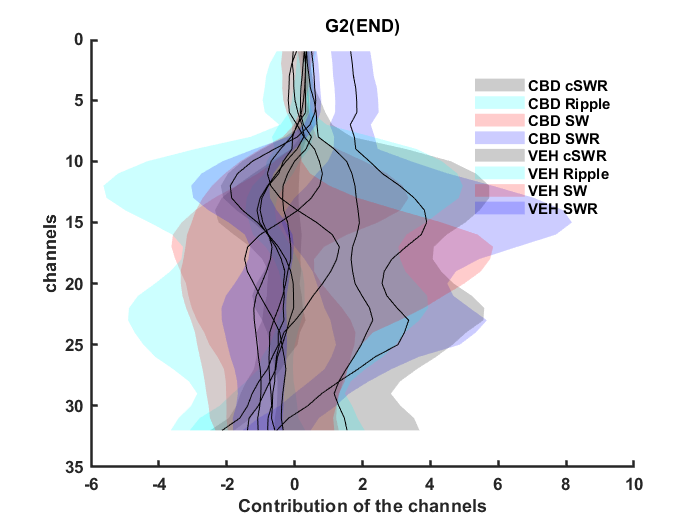


% Set line properties (black lines)
set(hl_g2, 'Color', 'k', 'LineWidth', 0.5);

legend(hl_g2,'CBD cSWR','CBD Ripple','CBD SW','CBD SWR','VEH cSWR','VEH Ripple','VEH SW','VEH SWR','Location','best')
legend(hp_g2,'CBD cSWR','CBD Ripple','CBD SW','CBD SWR','VEH cSWR','VEH Ripple','VEH SW','VEH SWR','Location','best')
legend boxoff
xlabel('Contribution of the channels')
% ylim([-10 10])
ylabel('channels')
set(gca,'FontSize',10,'LineWidth',1.5,'FontWeight','bold','FontName','Arial')
title('G2(END)') 
set(gcf,'Color','w')
set(gca,'YDir','reverse')

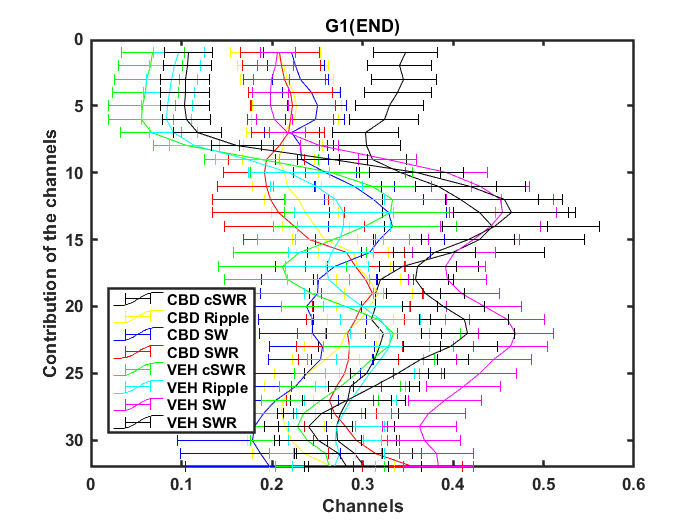

%G1
figure;

% Plot CBD data with error bars
errorbar( Average_CBD_CSWR(:,1),timevect, Sem_CBD_CSWR(:,1),'horizontal', 'k','LineWidth', 0.5);
hold on;
errorbar( Average_CBD_Ripple(:,1),timevect, Sem_CBD_Ripple(:,1),'horizontal', 'y','LineWidth', 0.5);
errorbar( Average_CBD_SW(:,1),timevect, Sem_CBD_SW(:,1),'horizontal', 'b','LineWidth', 0.5);
errorbar( Average_CBD_SWR(:,1),timevect, Sem_CBD_SWR(:,1),'horizontal', 'r','LineWidth', 0.5);

% Plot VEH data with error bars
errorbar( Average_VEH_CSWR(:,1),timevect, Sem_VEH_CSWR(:,1),'horizontal', 'g','LineWidth', 0.5);
errorbar( Average_VEH_Ripple(:,1),timevect, Sem_VEH_Ripple(:,1),'horizontal', 'c','LineWidth', 0.5);
errorbar( Average_VEH_SW(:,1),timevect, Sem_VEH_SW(:,1),'horizontal', 'm','LineWidth', 0.5);
errorbar( Average_VEH_SWR(:,1),timevect, Sem_VEH_SWR(:,1),'horizontal', 'k','LineWidth', 0.5);

legend('CBD cSWR','CBD Ripple','CBD SW','CBD SWR','VEH cSWR','VEH Ripple','VEH SW','VEH SWR','Location','best')
xlabel('Channels')
ylim([0 32])
xlim([-1 1])
ylabel('Contribution of the channels')
set(gca,'FontSize',10,'LineWidth',1.5,'FontWeight','bold','FontName','Arial')
title('G1(END)') 
set(gcf,'Color','w')
set(gca,'YDir','reverse')

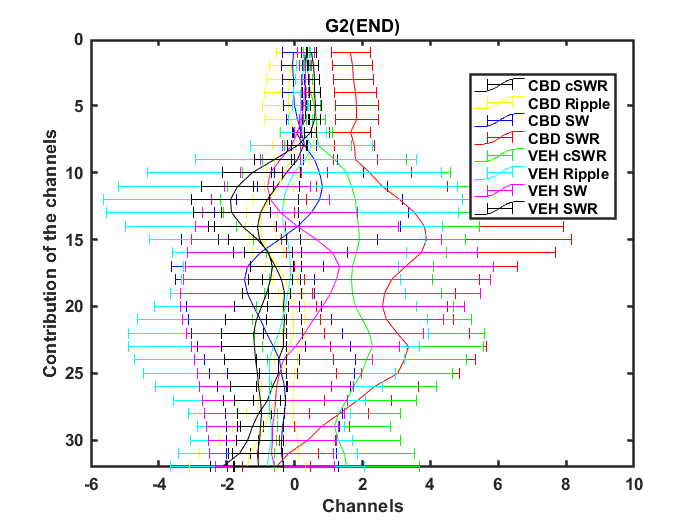

%................
%G2

figure;

% Plot CBD data with error bars
errorbar( Average_CBD_CSWR(:,2),timevect, Sem_CBD_CSWR(:,2),'horizontal', 'k','LineWidth', 0.5);
hold on;
errorbar( Average_CBD_Ripple(:,2),timevect, Sem_CBD_Ripple(:,2),'horizontal', 'y','LineWidth', 0.5);
errorbar( Average_CBD_SW(:,2),timevect, Sem_CBD_SW(:,2),'horizontal', 'b','LineWidth', 0.5);
errorbar( Average_CBD_SWR(:,2),timevect, Sem_CBD_SWR(:,2),'horizontal', 'r','LineWidth', 0.5);

% Plot VEH data with error bars
errorbar( Average_VEH_CSWR(:,2),timevect, Sem_VEH_CSWR(:,2),'horizontal', 'g','LineWidth', 0.5);
errorbar( Average_VEH_Ripple(:,2),timevect, Sem_VEH_Ripple(:,2),'horizontal', 'c','LineWidth', 0.5);
errorbar( Average_VEH_SW(:,2),timevect, Sem_VEH_SW(:,2),'horizontal', 'm','LineWidth', 0.5);
errorbar( Average_VEH_SWR(:,2),timevect, Sem_VEH_SWR(:,2),'horizontal', 'k','LineWidth', 0.5);

legend('CBD cSWR','CBD Ripple','CBD SW','CBD SWR','VEH cSWR','VEH Ripple','VEH SW','VEH SWR','Location','best')
xlabel('Channels')
ylim([0 32])
xlim([-10 10])
ylabel('Contribution of the channels')
set(gca,'FontSize',10,'LineWidth',1.5,'FontWeight','bold','FontName','Arial')
title('G2(END)') 
set(gcf,'Color','w')
set(gca,'YDir','reverse')

%G1-CBD
figure;
timevect=1:32

timevect =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32


[hl_g1, hp_g1] = boundedline( ...
     Average_CBD_CSWR(:,1),timevect,  Sem_CBD_CSWR(:,1)' ,'k', 'alpha', ...
     Average_CBD_Ripple(:,1),timevect,Sem_CBD_Ripple(:,1)','c','alpha', ...
     Average_CBD_SW(:,1),timevect,    Sem_CBD_SW(:,1)','r','alpha',  ...
     Average_CBD_SWR(:,1),timevect,   Sem_CBD_SWR(:,1)','b','alpha','orientation', 'horiz')

hl_g1 =   4×1 Line array:

  Line
  Line
  Line
  Line


hp_g1 =   4×1 Patch array:

  Patch
  Patch
  Patch
  Patch


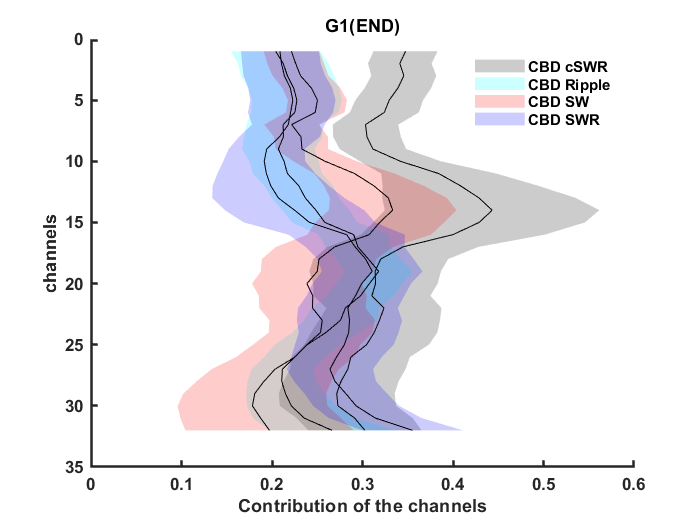



% Set line properties (black lines)
set(hl_g1, 'Color', 'k', 'LineWidth', 0.5);

legend(hl_g1,'CBD cSWR','CBD Ripple','CBD SW','CBD SWR','Location','best')
legend(hp_g1,'CBD cSWR','CBD Ripple','CBD SW','CBD SWR','Location','best')
legend boxoff
xlabel('Contribution of the channels')
% ylim([0 1])
xlim([-1 1])
ylabel('channels')
set(gca,'FontSize',10,'LineWidth',1.5,'FontWeight','bold','FontName','Arial')
title('G1(END)') 
set(gcf,'Color','w')
set(gca,'YDir','reverse')

%............................
%G1-VEH
figure;
timevect=1:32

timevect =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32


[hl_g1, hp_g1] = boundedline( ...
     Average_VEH_CSWR(:,1),timevect,  Sem_VEH_CSWR(:,1)' ,'g','alpha', ...
     Average_VEH_Ripple(:,1),timevect,Sem_VEH_Ripple(:,1)','m','alpha',...
     Average_VEH_SW(:,1),timevect,    Sem_VEH_SW(:,1)','y','alpha',  ...
     Average_VEH_SWR(:,1),timevect,   Sem_VEH_SWR(:,1)','b','alpha', 'orientation', 'horiz')

hl_g1 =   4×1 Line array:

  Line
  Line
  Line
  Line


hp_g1 =   4×1 Patch array:

  Patch
  Patch
  Patch
  Patch


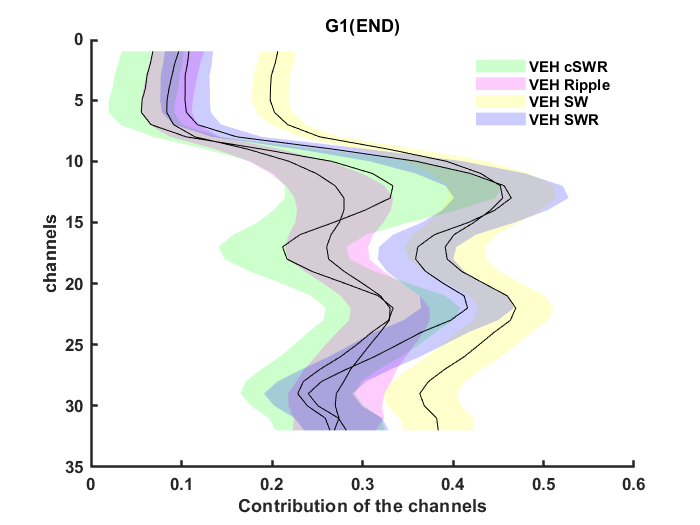


% Set line properties (black lines)
set(hl_g1, 'Color', 'k', 'LineWidth', 0.5);

legend(hl_g1,'VEH cSWR','VEH Ripple','VEH SW','VEH SWR','Location','best')
legend(hp_g1,'VEH cSWR','VEH Ripple','VEH SW','VEH SWR','Location','best')
legend boxoff
xlabel('Contribution of the channels')
% ylim([0 1])
xlim([-1 1])
ylabel('channels')
set(gca,'FontSize',10,'LineWidth',1.5,'FontWeight','bold','FontName','Arial')
title('G1(END)') 
set(gcf,'Color','w')
set(gca,'YDir','reverse')

%.........................
%G2-CBD
figure;
timevect=1:32

timevect =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32


[hl_g1, hp_g1] = boundedline( ...
     Average_CBD_CSWR(:,2),timevect,  Sem_CBD_CSWR(:,2)' ,'k', 'alpha', ...
     Average_CBD_Ripple(:,2),timevect,Sem_CBD_Ripple(:,2)','c','alpha', ...
     Average_CBD_SW(:,2),timevect,    Sem_CBD_SW(:,2)','r','alpha',  ...
     Average_CBD_SWR(:,2),timevect,   Sem_CBD_SWR(:,2)','b','alpha','orientation', 'horiz')

hl_g1 =   4×1 Line array:

  Line
  Line
  Line
  Line


hp_g1 =   4×1 Patch array:

  Patch
  Patch
  Patch
  Patch


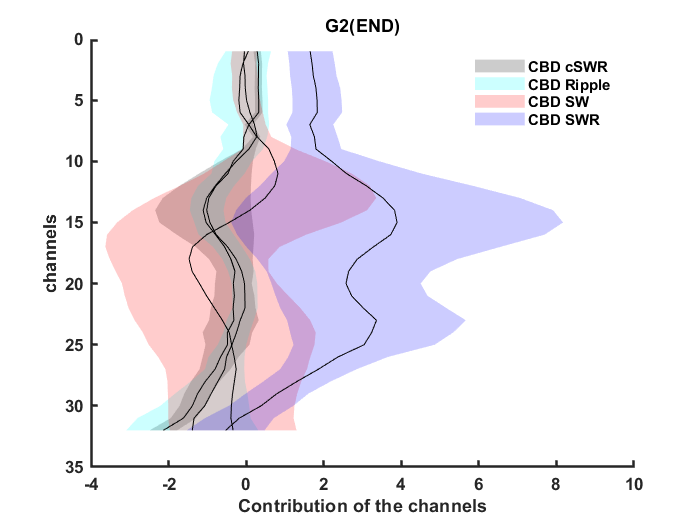



% Set line properties (black lines)
set(hl_g1, 'Color', 'k', 'LineWidth', 0.5);

legend(hl_g1,'CBD cSWR','CBD Ripple','CBD SW','CBD SWR','Location','best')
legend(hp_g1,'CBD cSWR','CBD Ripple','CBD SW','CBD SWR','Location','best')
legend boxoff
xlabel('Contribution of the channels')
% ylim([0 1])
xlim([-10 10])
ylabel('channels')
set(gca,'FontSize',10,'LineWidth',1.5,'FontWeight','bold','FontName','Arial')
title('G2(END)') 
set(gcf,'Color','w')
set(gca,'YDir','reverse')

%...........
%G2-VEH
figure;
timevect=1:32

timevect =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32


[hl_g1, hp_g1] = boundedline( ...
     Average_VEH_CSWR(:,2),timevect,  Sem_VEH_CSWR(:,2)' ,'g','alpha', ...
     Average_VEH_Ripple(:,2),timevect,Sem_VEH_Ripple(:,2)','m','alpha',...
     Average_VEH_SW(:,2),timevect,    Sem_VEH_SW(:,2)','y','alpha',  ...
     Average_VEH_SWR(:,2),timevect,   Sem_VEH_SWR(:,2)','b','alpha', 'orientation', 'horiz')

hl_g1 =   4×1 Line array:

  Line
  Line
  Line
  Line


hp_g1 =   4×1 Patch array:

  Patch
  Patch
  Patch
  Patch


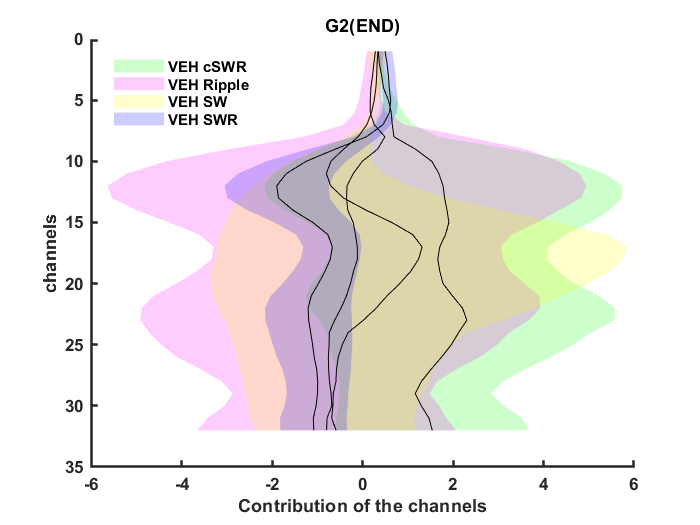


% Set line properties (black lines)
set(hl_g1, 'Color', 'k', 'LineWidth', 0.5);

legend(hl_g1,'VEH cSWR','VEH Ripple','VEH SW','VEH SWR','Location','best')
legend(hp_g1,'VEH cSWR','VEH Ripple','VEH SW','VEH SWR','Location','best')
legend boxoff
xlabel('Contribution of the channels')
% ylim([0 1])
xlim([-10 10])
ylabel('channels')
set(gca,'FontSize',10,'LineWidth',1.5,'FontWeight','bold','FontName','Arial')
title('G2(END)') 
set(gcf,'Color','w')
set(gca,'YDir','reverse')

# Average of all conditions (CBD&VEH)

Mean_all_condi_CBD= mean(cat(3,Average_CBD_CSWR,Average_CBD_Ripple,Average_CBD_SW,Average_CBD_SWR),3)

Mean_all_condi_CBD =     0.2455    0.4871
    0.2476    0.4674
    0.2520    0.4661
    0.2567    0.4808
    0.2576    0.4940
    0.2544    0.5253
    0.2388    0.4987
    0.2395    0.5643
    0.2364    0.5950
    0.2513    0.5860


Mean_all_condi_VEH=mean(cat(3,Average_VEH_CSWR,Average_VEH_Ripple,Average_VEH_SW,Average_VEH_SWR),3)

Mean_all_condi_VEH =     0.1200    0.3685
    0.1171    0.3719
    0.1136    0.3822
    0.1122    0.3842
    0.1106    0.4064
    0.1119    0.4008
    0.1231    0.3673
    0.1584    0.2945
    0.2389    0.1219
    0.3092   -0.1036



Sem_all_condi_CBD = squeeze(std(cat(3,Average_CBD_CSWR,Average_CBD_Ripple,Average_CBD_SW,Average_CBD_SWR),0, 3) / sqrt(4));
Sem_all_condi_VEH = squeeze(std(cat(3,Average_VEH_CSWR,Average_VEH_Ripple,Average_VEH_SW,Average_VEH_SWR),0, 3) / sqrt(4));

%plot
%G1
figure;
timevect=1:32

timevect =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32


[hl_g2, hp_g2] = boundedline( ...
    Mean_all_condi_CBD(:,1),timevect,Sem_all_condi_CBD(:,1),'g','alpha',...
    Mean_all_condi_VEH(:,1),timevect,Sem_all_condi_VEH(:,1),'k','alpha','orientation', 'horiz')

hl_g2 =   2×1 Line array:

  Line
  Line


hp_g2 =   2×1 Patch array:

  Patch
  Patch


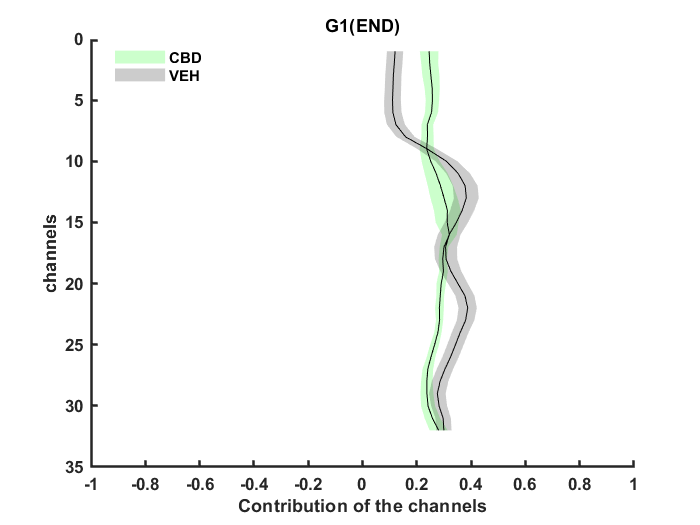

% Set line properties (black lines)
set(hl_g2, 'Color', 'k', 'LineWidth', 0.5);
legend(hl_g2,'CBD','VEH','Location','best')
legend(hp_g2,'CBD','VEH','Location','best')
legend boxoff
xlabel('Contribution of the channels')
% ylim([-10 10])
xlim([-1 1])
ylabel('channels')
set(gca,'FontSize',10,'LineWidth',1.5,'FontWeight','bold','FontName','Arial')
title('G1(END)') 
set(gcf,'Color','w')
set(gca,'YDir','reverse')

%G2
figure;
timevect=1:32

timevect =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32


[hl_g2, hp_g2] = boundedline( ...
    Mean_all_condi_CBD(:,2),timevect,Sem_all_condi_CBD(:,2),'g','alpha',...
    Mean_all_condi_VEH(:,2),timevect,Sem_all_condi_VEH(:,2),'k','alpha','orientation', 'horiz')

hl_g2 =   2×1 Line array:

  Line
  Line


hp_g2 =   2×1 Patch array:

  Patch
  Patch


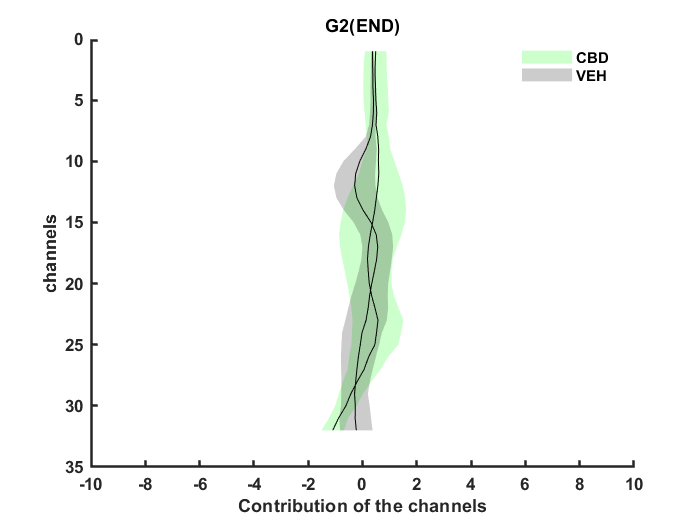

% Set line properties (black lines)
set(hl_g2, 'Color', 'k', 'LineWidth', 0.5);
legend(hl_g2,'CBD','VEH','Location','best')
legend(hp_g2,'CBD','VEH','Location','best')
legend boxoff
xlabel('Contribution of the channels')
% ylim([-10 10])
xlim([-2 2])
ylabel('channels')
set(gca,'FontSize',10,'LineWidth',1.5,'FontWeight','bold','FontName','Arial')
title('G2(END)') 
set(gcf,'Color','w')
set(gca,'YDir','reverse')

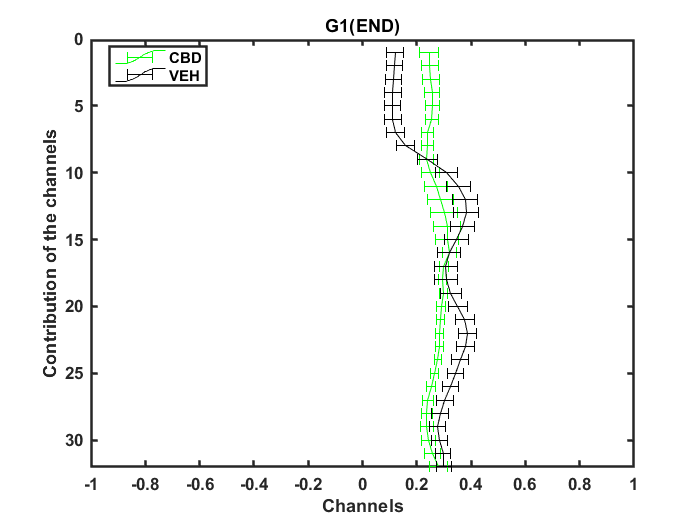

%.........................
%Errorbars
%G1
figure;

errorbar( Mean_all_condi_CBD(:,1),timevect, Sem_all_condi_CBD(:,1),'horizontal', 'g','LineWidth', 0.5);
hold on;
errorbar( Mean_all_condi_VEH(:,1),timevect, Sem_all_condi_VEH(:,1),'horizontal', 'k','LineWidth', 0.5);


legend('CBD','VEH','Location','best')
xlabel('Channels')
ylim([0 32])
xlim([-1 1])
ylabel('Contribution of the channels')
set(gca,'FontSize',10,'LineWidth',1.5,'FontWeight','bold','FontName','Arial')
title('G1(END)') 
set(gcf,'Color','w')
set(gca,'YDir','reverse')

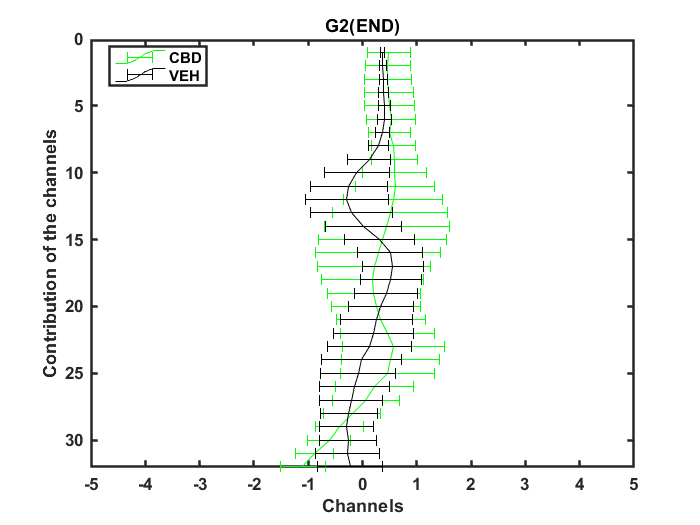

%G2
figure;

errorbar( Mean_all_condi_CBD(:,2),timevect, Sem_all_condi_CBD(:,2),'horizontal', 'g','LineWidth', 0.5);
hold on;
errorbar( Mean_all_condi_VEH(:,2),timevect, Sem_all_condi_VEH(:,2),'horizontal', 'k','LineWidth', 0.5);


legend('CBD','VEH','Location','best')
xlabel('Channels')
ylim([0 32])
xlim([-5 5])
ylabel('Contribution of the channels')
set(gca,'FontSize',10,'LineWidth',1.5,'FontWeight','bold','FontName','Arial')
title('G2(END)') 
set(gcf,'Color','w')
set(gca,'YDir','reverse')